# Rexam 2017

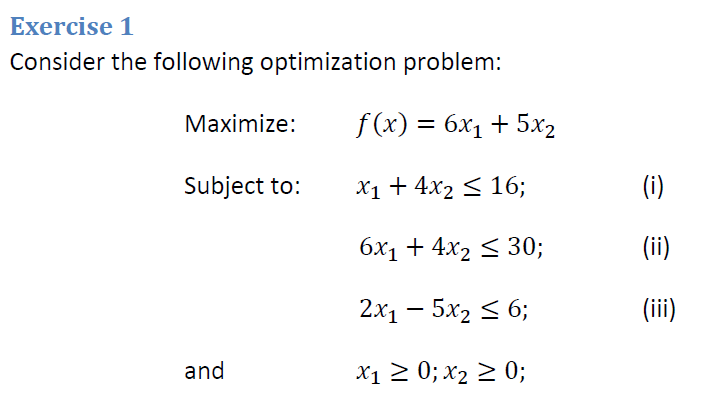

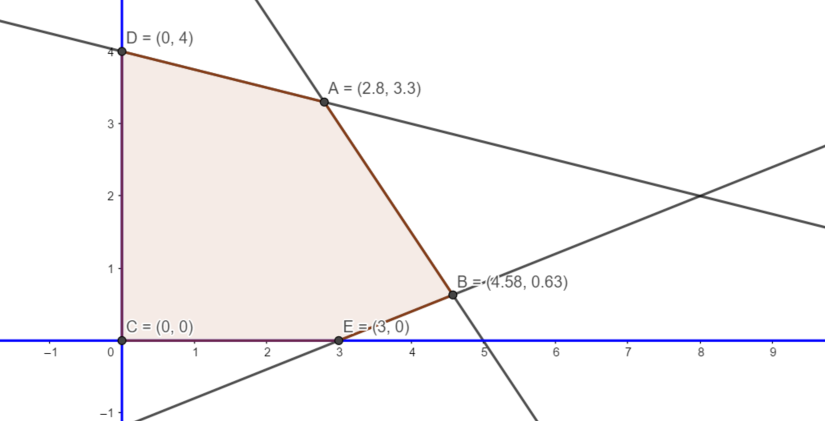

Point A : (2.8, 3.3), Point B : (4.58,0.63), Point C : (0,0), Point D : (0,4) ,Point E : (3,0) 

**Objective function results**


$$f\left(x\right)=6x_1 +5x_2$$


Inputing the different solutions to maximize the objective function:

F_A = 6*2.8 + 5*3.3;
F_B = 6*4.58 + 5*0.63;
F_C = 6*0 + 5*0;
F_D = 6*0 + 5*4;
F_E = 6*3 + 5*0;

fprintf("Our maxpoint is A[2.8,3.3] with the following value: %.2f", F_A )

Our maxpoint is A[2.8,3.3] with the following value: 33.30

The solution for the max of the objective function is $x_1 =2\ldotp 8\;,x_2 =3\ldotp 3\;,\max =33\ldotp 30$

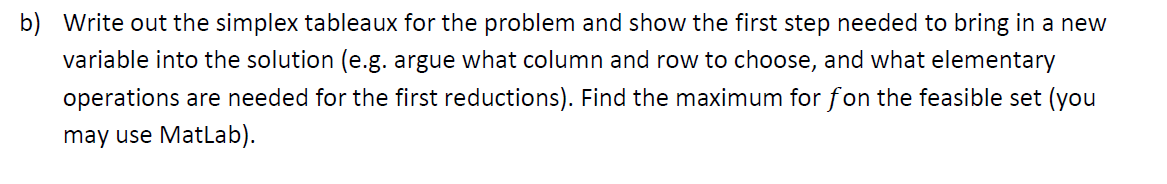

% Simplex tuable for the problem  
% Step change inquality to equality by adding slacks var
%    x1   x2,   s1   s2  s3    M     B  
A = [1,    4,   1,   0,   0,   0,   16;
     6,    4,   0,   1,   0,   0,   30;
     2,   -5,   0,   0,   1,   0,   6;
     -6,  -5,   0,   0,   0,   1,   0]

A =      1     4     1     0     0     0    16
     6     4     0     1     0     0    30
     2    -5     0     0     1     0     6
    -6    -5     0     0     0     1     0


% Step two, find most negative --> they are equal -- we take x1
% Step three a positive ratio than is smallets 
% B/entry  for all entries
% 16/1 = 16  |   30/6 = 5    |    6/2 = 3     --> pivot x1 at row3

% Row operations to finish pivot collum

% R3 * 1/2
A(3,:) = 1/2 * A(3,:)

A =     1.0000    4.0000    1.0000         0         0         0   16.0000
    6.0000    4.0000         0    1.0000         0         0   30.0000
    1.0000   -2.5000         0         0    0.5000         0    3.0000
   -6.0000   -5.0000         0         0         0    1.0000         0


% R4 + 3R3
A(4,:) =  6*A(3,:) + A(4,:)

A =     1.0000    4.0000    1.0000         0         0         0   16.0000
    6.0000    4.0000         0    1.0000         0         0   30.0000
    1.0000   -2.5000         0         0    0.5000         0    3.0000
         0  -20.0000         0         0    3.0000    1.0000   18.0000


% R2- 3R3
A(2,:) = A(2,:) - 6*A(3,:)

A =     1.0000    4.0000    1.0000         0         0         0   16.0000
         0   19.0000         0    1.0000   -3.0000         0   12.0000
    1.0000   -2.5000         0         0    0.5000         0    3.0000
         0  -20.0000         0         0    3.0000    1.0000   18.0000


% R1 - 1/2*R3
A(1,:) = A(1,:) -  A(3,:)

A =          0    6.5000    1.0000         0   -0.5000         0   13.0000
         0   19.0000         0    1.0000   -3.0000         0   12.0000
    1.0000   -2.5000         0         0    0.5000         0    3.0000
         0  -20.0000         0         0    3.0000    1.0000   18.0000


This is the first iteration the the simplex alogorithm, if we wanted to we could continue with the next interation...

- We will check to result of the algorithm, by running it.

x1 = optimvar('x1');
x2 = optimvar('x2');
prob = optimproblem('Objective',6*x1 +5*x2,'ObjectiveSense','max');
prob.Constraints.c1 = x1 +4*x2 <= 16;
prob.Constraints.c2 = 6*x1 + 4*x2 <= 30;
prob.Constraints.c3 = 2*x1-5*x2 <= 6;
prob.Constraints.c4 = x1 >= 0;
prob.Constraints.c5 = x2 >= 0;

problem = prob2struct(prob);
[sol,fval,exitflag,output] = linprog(problem);

Optimal solution found.



fprintf("Our maxpoint is [x1, x2]  = [ %.2f,  %.2f] --> This is the same solution obtained from the geograhpic solution", sol )

Our maxpoint is [x1, x2]  = [ 2.80,  3.30] --> This is the same solution obtained from the geograhpic solution

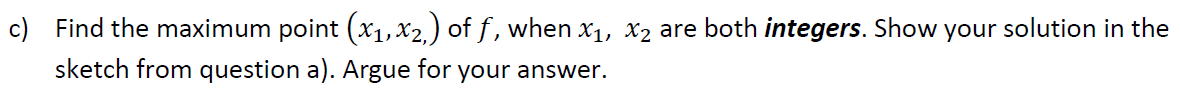

Looking at the graph, the found maximum was [x1,x2]  = [2.80, 3-30 ]--> Since we only are restricted to integeres, we can strech to 2,80 and 3,30. We can round each cordinate down and find the next solution.

F_A = 6*floor(2.8) + 5*floor(3.3)

F_A = 27

F_B = 6*floor(4.58) + 5*floor(0.63)

F_B = 24

F_C = 6*0 + 5*0

F_C = 0

F_D = 6*0 + 5*4

F_D = 20

F_E = 6*3 + 5*0

F_E = 18

fprintf("Our maxpoint is A[2, 3] with the following value: %.2f", F_A )

Our maxpoint is A[2, 3] with the following value: 27.00

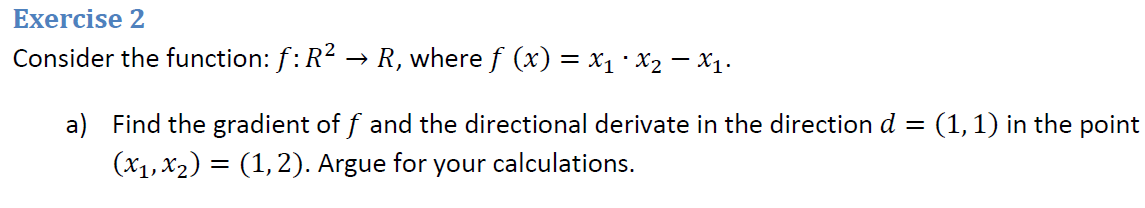

Gradiant of f is defined as : $\nabla f\left(x\right)=\left\lbrack \begin{array}{c}
\frac{\partial f}{\partial {\;x}_1 }\\
\frac{\partial f}{\partial {\;x}_2 }\\
\ldotp \ldotp \ldotp \\
\frac{\partial f}{\partial {\;x}_n }
\end{array}\right\rbrack \;$   First derivative-row vector is defined as : $D\;f\left(x\right)={\left(\nabla f\left(x\right)\right)}^T =\left\lbrack \begin{array}{cccc}
\frac{\partial f}{\partial {\;x}_1 } & \frac{\partial f}{\partial {\;x}_2 } & \ldotp \ldotp \ldotp  & \frac{\partial f}{\partial {\;x}_n }
\end{array}\right\rbrack$

We parcial differiance first for x1, then x2 $\nabla f\left(x\right)$

syms x1 x2
f = x1*x2-x1;
gradiant_f = gradient(f, [x1,x2]);
d_gradiant_f = transpose(gradiant_f)

$$d\_gradiant\_f = \left(\begin{array}{cc} x_{2}-1 & x_{1} \end{array}\right)$$

The can then calculate thte direction derivative as 


$${\frac{\partial f}{\partial d}\left(x\right)=\;\left(\nabla f\left(x\right)\right)}^T *d$$


We can then obtian the directional derevative : ${\left(\nabla f\left(x\right)\right)}^T *d$

d = [1, 1];
directional_derivative = d_gradiant_f*transpose(d)

$$directional\_derivative = x_{1}+x_{2}-1$$

point = [1,2];
% direction in the point [1,2] :
point_direction = 1 + 2 - 1

point_direction = 2

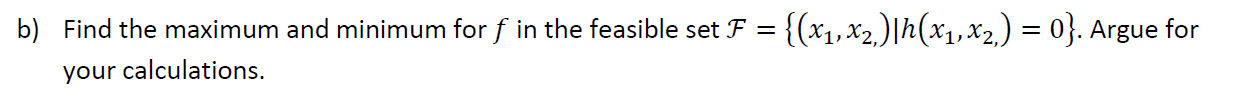

We will use the Lagrange multiplier for the problem


$$\nabla f\left(x\right)+\lambda *\nabla h\left(x\right)=0$$
 

We can solve the follwing problem by solving 3 linequeations with 3 uknowns

clearvars
syms x1 x2
f = x1*x2-x1;
gradiant_f = gradient(f, [x1,x2]);

clear x1 x2
syms x1 x2 lambda
h = x1^2 + x2^2 -4 

$$h = {x_{1}}^{2}+{x_{2}}^{2}-4$$

gradiant_h = gradient(h, [x1,x2])

$$gradiant\_h = \left(\begin{array}{c} 2\,x_{1}\\ 2\,x_{2} \end{array}\right)$$

% Lagrange multiplier
Lagrange_multiplier = gradiant_f + lambda* gradiant_h == 0

$$Lagrange\_multiplier = \left(\begin{array}{c} x_{2}+2\,\lambda \,x_{1}-1=0\\ x_{1}+2\,\lambda \,x_{2}=0 \end{array}\right)$$

% we now have 2 equation and 3 unknowns
% we can use the fuction h = 0 as the last one:
equation1 = Lagrange_multiplier(1)

$$equation1 = x_{2}+2\,\lambda \,x_{1}-1=0$$

equation2 = Lagrange_multiplier(2)

$$equation2 = x_{1}+2\,\lambda \,x_{2}=0$$

equation3 = x1^2 + x2^2 -4  == 0

$$equation3 = {x_{1}}^{2}+{x_{2}}^{2}-4=0$$

[x1,x2,lambda] = solve([equation1, equation2, equation3], [x1,x2, lambda]);
x1 = double(x1)

x1 =     1.0756
   -1.6103
   -1.0756
    1.6103


x2 = double(x2)

x2 =     1.6861
   -1.1861
    1.6861
   -1.1861


lambda = double(lambda)

lambda =    -0.3190
   -0.6788
    0.3190
    0.6788


% candidate coordinates 
s1 = [x1(1), x2(1)];
s2 = [x1(2), x2(2)];
s3 = [x1(3), x2(3)];
s4 = [x1(4), x2(4)];

% Solutions
f1 = s1(1)*s1(2)-s1(1)

f1 = 0.7380

f2 = s2(1)*s2(2)-s2(1)

f2 = 3.5203

f3 = s3(1)*s3(2)-s3(1)

f3 = -0.7380

f4 = s4(1)*s4(2)-s4(1)

f4 = -3.5203

fprintf("maximum: %.2f at point : (%.2f, %.2f) and minimum: %.2f at point (%.2f, %.2f)", f2, s2, f4, s4);

maximum: 3.52 at point : (-1.61, -1.19) and minimum: -3.52 at point (1.61, -1.19)

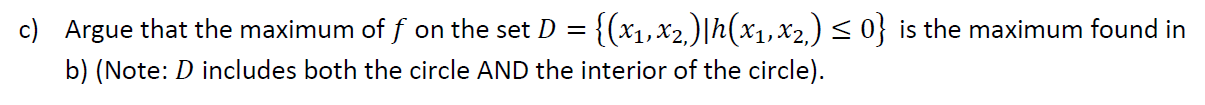

% HELLLLLP

clearvars;

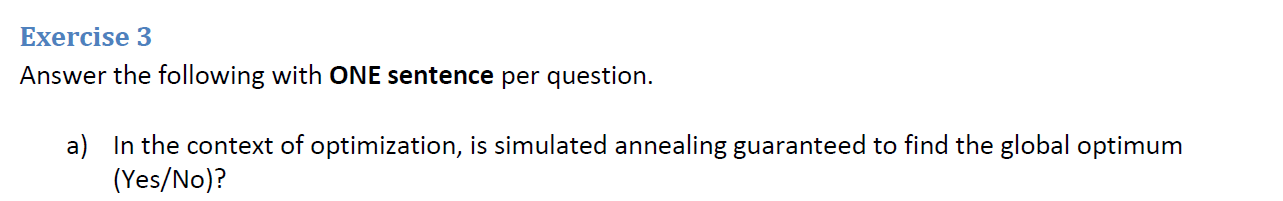

% Yes. If the simulated anneling algorithm have enough time.

% Continues optimazation invloves, computation on data set that are
% continues. (Not countalbe)

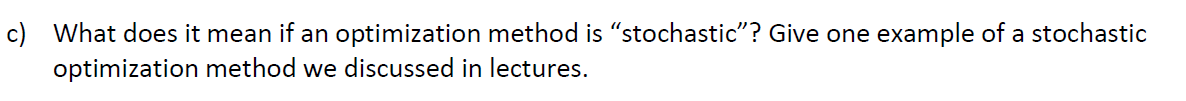

% It means that on a given input the decision the method will choose each iteration is not the same each time running the second time. 
% Probabilistic is included. Example could be swarm.

% In each iteratates there is a set of candidate solutions to choose from. 
% An eazample could be particle swam algotihms. Each interation, each particle has a candidate soultion.

    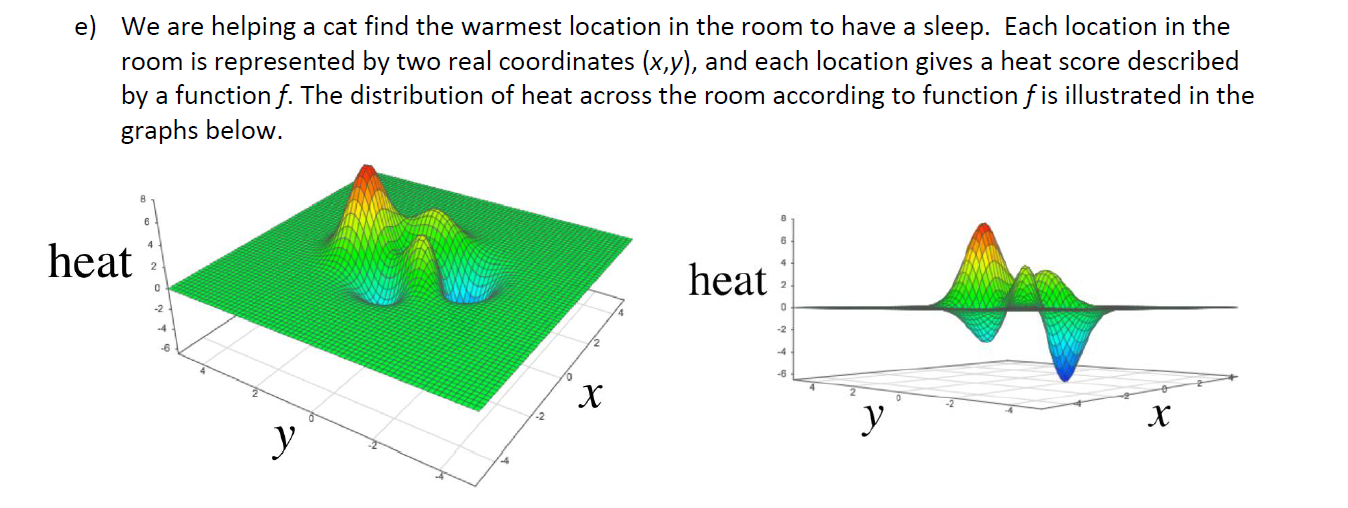

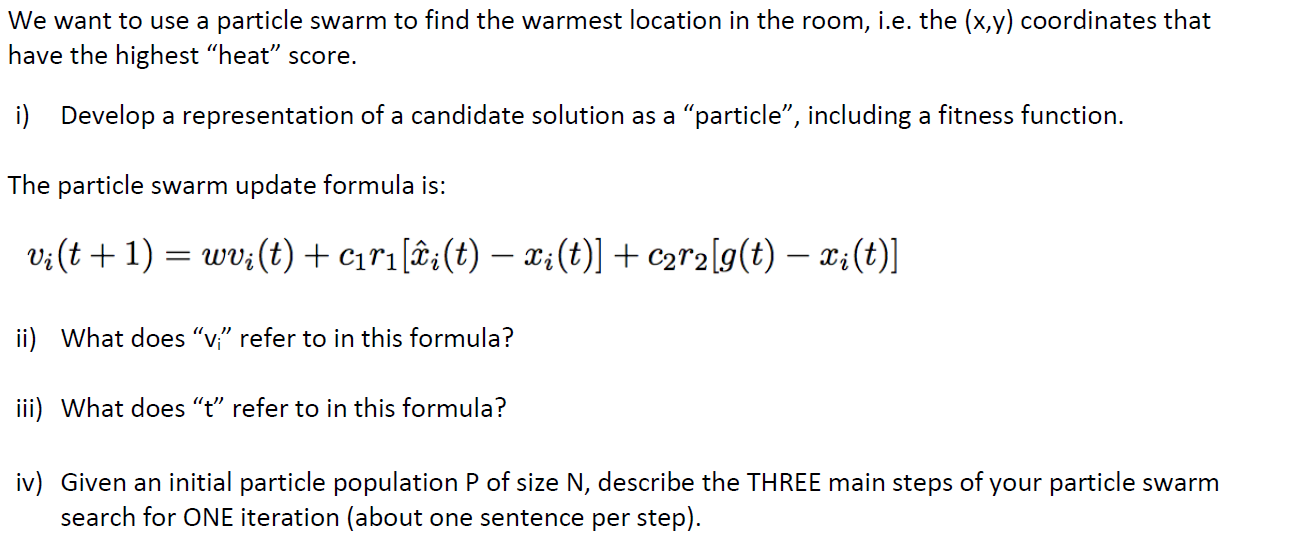

% I) Help what the fuck is a fitness value
% HEEEELP 

% II)
% The current "i" partical in the swarm

% III) 
% The current time of the swarm computation in terms of "iterations "

% IV) 
% 1  evaluate fitness of the curent particle
% 2. update individual and global fitness
% 3. update individual velocity and position

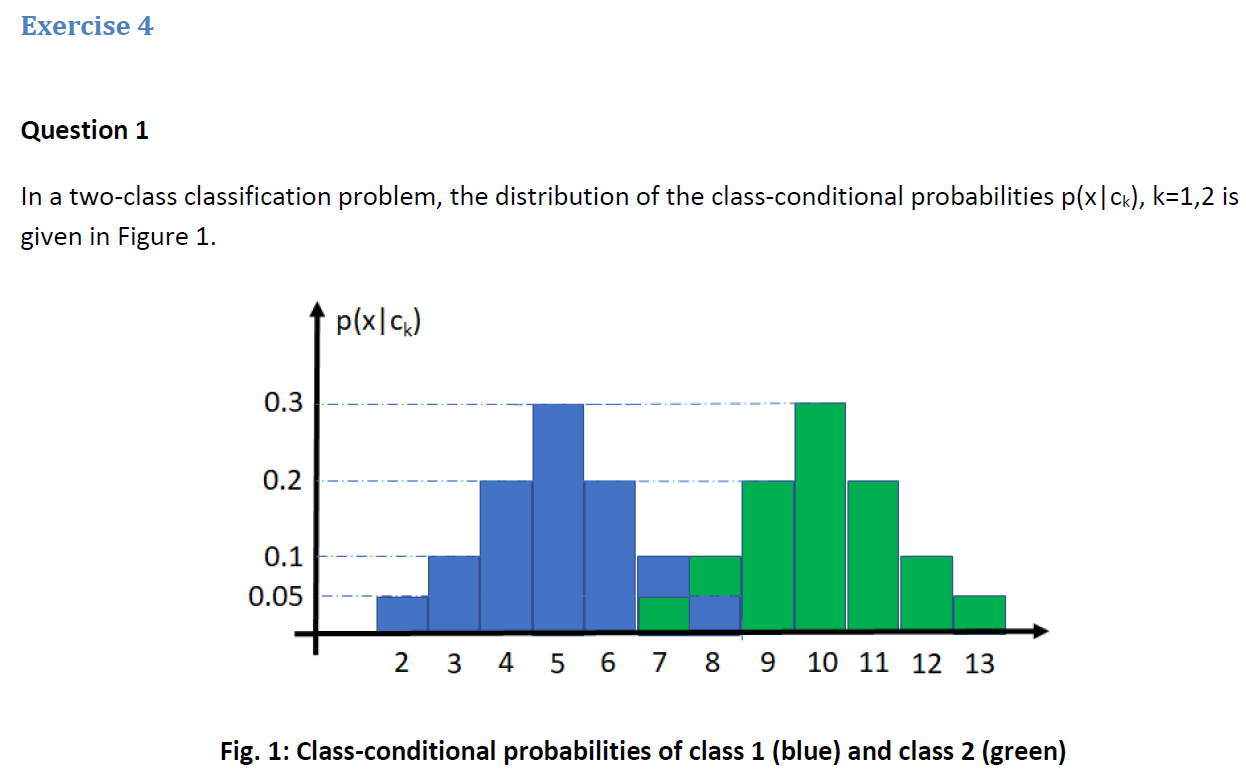

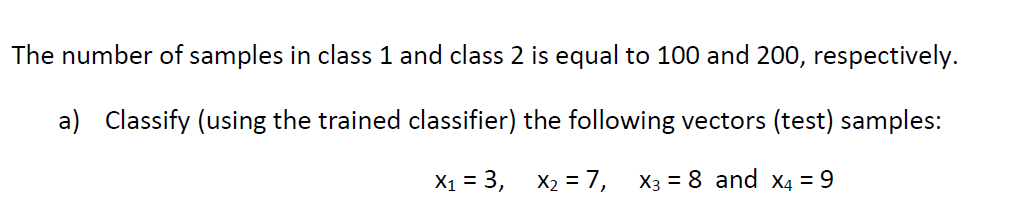

We will use the bayes formula to calculate the  $P\left(c_k |\;x\right)$ since we alreaddy have $p\left(x\;|\;c_k \right)$ given for every x in the trained model we can use bayers rule, to get $P\left(c_k \left|\;x\right.\right)$. Note that ine the decision function $P\left(x\right)$ gets canceled out:


$$P\left(c_k |x\;\right)=\frac{P\left(x|c_k \;\right)*P\left(c_k \right)}{P\left(x\right)}\;$$


We will use this decision function to decide the class:

$P\left(c_1 \left|x\;\right.\right)$> $P\left(c_2 \left|x\;\right.\right)$  

inserting from bayers we get:

 
$$\frac{P\left(x|c_1 \right)*P\left(c_1 \right)}{P\left(x\right)}>\frac{P\left(x|c_2 \;\right)*P\left(c_2 \right)}{P\left(x\right)}$$


Multiply by P(X), it cancels out.


$$P\left(x|c_1 \right)*P\left(c_1 \right)>P\left(x\left|c_2 \;\right.\right)*P\left(c_2 \right)$$


% for x = 3
p_x_3_given_c1 = 0.1;
p_c1 = 100/(100+200);
prob_c1_given_x3 = p_x_3_given_c1*p_c1;

p_x_3_given_c2 = 0;
p_c2 = 200/(100+200);
prob_c2_given_x3 =  p_x_3_given_c2*p_c2;

if prob_c1_given_x3 > prob_c2_given_x3
    fprintf("for x = 3 : p(ck= 1| x) > p(ck= 2| x)  => %.3f > %.3f  we choose class 1", prob_c1_given_x3, prob_c2_given_x3);
else
    fprintf("for x = 3 : p(ck= 1| x) < p(ck= 2| x)  => %.3f < %.3f  we choose class 2", prob_c1_given_x3, prob_c2_given_x3);
end

for x = 3 : p(ck= 1| x) > p(ck= 2| x)  => 0.033 > 0.000  we choose class 1

% for x = 7
p_x_7_given_c1 = 0.1;
p_c1 = 100/(100+200);
prob_c1_given_x7 = p_x_7_given_c1*p_c1;

p_x_7_given_c2 = 0.05;
p_c2 = 200/(100+200);
prob_c2_given_x7 =  p_x_7_given_c2*p_c2;

if prob_c1_given_x7 > prob_c2_given_x7
    fprintf("for x = 7 : p(ck= 1| x) > p(ck= 2| x)  => %.3f > %.3f  we choose class 1", prob_c1_given_x7, prob_c2_given_x7);
elseif prob_c1_given_x7 == prob_c2_given_x7   
    fprintf("for x = 7 : p(ck= 1| x) == p(ck= 2| x)  => %.3f == %.3f  we choose class to the right = class 2", prob_c1_given_x7, prob_c2_given_x7);
else
    fprintf("for x = 7 : p(ck= 1| x) < p(ck= 2| x)  => %.3f < %.3f  we choose class 2", prob_c1_given_x7, prob_c2_given_x7);
 
end

for x = 7 : p(ck= 1| x) == p(ck= 2| x)  => 0.033 == 0.033  we choose class to the right = class 2

% for x = 8
p_x_8_given_c1 = 0.05;
p_c1 = 100/(100+200);
prob_c1_given_x8 = p_x_8_given_c1*p_c1;

p_x_8_given_c2 = 0.1;
p_c2 = 200/(100+200);
prob_c2_given_x8 =  p_x_8_given_c2*p_c2;

if prob_c1_given_x8 > prob_c2_given_x8
    fprintf("for x = 8 : p(ck= 1| x) > p(ck= 2| x)  => %.3f > %.3f  we choose class 1", prob_c1_given_x8, prob_c2_given_x8);
else
    fprintf("for x = 8 : p(ck= 1| x) < p(ck= 2| x)  => %.3f < %.3f  we choose class 2", prob_c1_given_x8, prob_c2_given_x8);
end

for x = 8 : p(ck= 1| x) < p(ck= 2| x)  => 0.017 < 0.067  we choose class 2

% for x = 9
p_x_9_given_c1 = 0;
p_c1 = 100/(100+200);
prob_c1_given_x9 = p_x_9_given_c1*p_c1;

p_x_9_given_c2 = 0.2;
p_c2 = 200/(100+200);
prob_c2_given_x9 =  p_x_9_given_c2*p_c2;

if prob_c1_given_x9 > prob_c2_given_x9
    fprintf("for x = 9 : p(ck= 1| x) > p(ck= 2| x)  => %.3f > %.3f  we choose class 1", prob_c1_given_x9, prob_c2_given_x9);
else
    fprintf("for x = 9 : p(ck= 1| x) < p(ck= 2| x)  => %.3f < %.3f  we choose class 2", prob_c1_given_x9, prob_c2_given_x9);
end

for x = 9 : p(ck= 1| x) < p(ck= 2| x)  => 0.000 < 0.133  we choose class 2

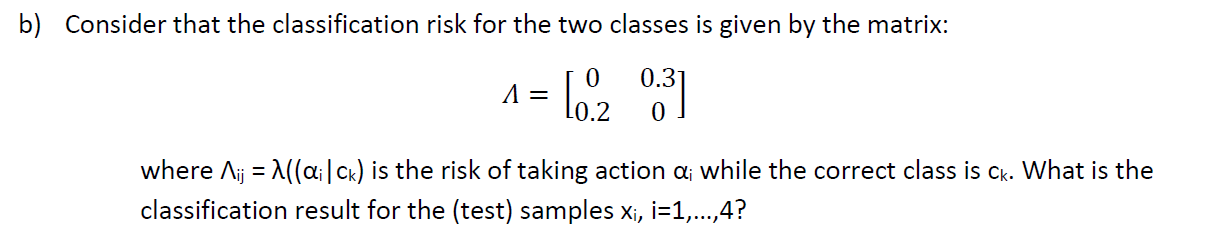

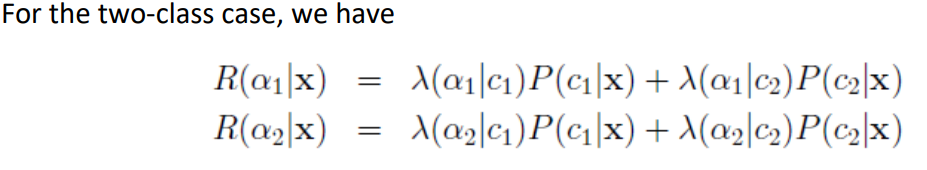

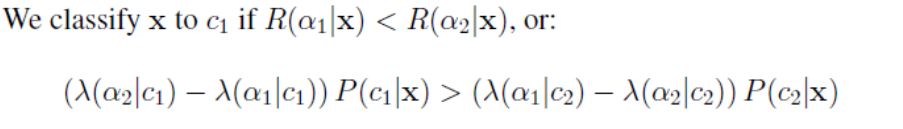

A = [ 0,   0.3;
      0.2,   0];

% i = 1, x = 3
R_a1_given_x_3 = A(1,1)*prob_c1_given_x3 + A(1,2)*prob_c2_given_x3;
R_a2_given_x_3 = A(2,1)*prob_c1_given_x3 + A(2,2)*prob_c2_given_x3;

if R_a1_given_x_3 < R_a2_given_x_3
    fprintf("R(a1|x3) < R(a2|x3) <--> %.5f < %.5f  --> we choose class 1", R_a1_given_x_3, R_a2_given_x_3);
else
    fprintf("R(a1|x3) > R(a2|x3) <--> %.5f < %.5f --> we choose class 2", R_a1_given_x_3, R_a2_given_x_3);
end

R(a1|x3) < R(a2|x3) <--> 0.00000 < 0.00667  --> we choose class 1

% i = 2, x = 7
R_a1_given_x_7 = A(1,1)*prob_c1_given_x7 + A(1,2)*prob_c2_given_x7;
R_a2_given_x_7 = A(2,1)*prob_c1_given_x7 + A(2,2)*prob_c2_given_x7;

if R_a1_given_x_7 < R_a2_given_x_7
    fprintf("R(a1|x3) < R(a2|x3) <--> %.5f < %.5f  --> we choose class 1", R_a1_given_x_7, R_a2_given_x_7);
else
    fprintf("R(a1|x3) > R(a2|x3) <--> %.5f > %.5f  --> we choose class 2", R_a1_given_x_7, R_a2_given_x_7);
end

R(a1|x3) > R(a2|x3) <--> 0.01000 < 0.00667  --> we choose class 2

% i = 3, x = 8
R_a1_given_x_8 = A(1,1)*prob_c1_given_x8 + A(1,2)*prob_c2_given_x8;
R_a2_given_x_8 = A(2,1)*prob_c1_given_x8 + A(2,2)*prob_c2_given_x8;

if R_a1_given_x_8 < R_a2_given_x_8
    fprintf("R(a1|x3) < R(a2|x3) <--> %.5f < %.5f --> we choose class 1", R_a1_given_x_8, R_a2_given_x_8);
else
    fprintf("R(a1|x3) > R(a2|x3) <--> %.5f > %.5f --> we choose class 2", R_a1_given_x_8, R_a2_given_x_8);
end

R(a1|x3) > R(a2|x3) <--> 0.02000 < 0.00333 --> we choose class 2

% i = 4, x = 9
R_a1_given_x_9 = A(1,1)*prob_c1_given_x9 + A(1,2)*prob_c2_given_x9;
R_a2_given_x_9 = A(2,1)*prob_c1_given_x9 + A(2,2)*prob_c2_given_x9;

if R_a1_given_x_9 < R_a2_given_x_9
    fprintf("R(a1|x3) < R(a2|x3) <--> %.5f < %.5f  --> we choose class 1", R_a1_given_x_9, R_a2_given_x_9);
else
    fprintf("R(a1|x3) > R(a2|x3) <--> %.5f > %.5f  --> we choose class 2", R_a1_given_x_9, R_a2_given_x_9);
end

R(a1|x3) > R(a2|x3) <--> 0.04000 < 0.00000  --> we choose class 2